rng(14);
n=500;
% rand1 = exprnd(.16,[1,floor(n/3)]);
% rand1 = rand1(rand1<=0.6);
% rand1 = rand1(rand1>0);
% rand3 = exprnd(0.12,[1,floor(n/3)])+0.5;
% rand3 = rand3(rand3<=1);
% rand3 = rand3(rand3>0.5);
lower = 0;
peak = 0.2;
upper = 0.8;
pd = makedist('Triangular','A',lower,'B',peak,'C',upper);
y = random(pd,1,n);

% y = ([rand1])

% y = y(y<=1);
sum(y<0)

ans = 0

sum(y>1)

ans = 0


% knots = [-0.5, 0.0, 0.1, 0.21, 0.31, 0.41, 0.51, 0.6, 0.71, 0.81, 0.91, 1, 1.5];
% d = 11;
knots = [-1e100, 0, 0.11, 0.26, 0.34, 0.38, 0.48, 0.56, 0.7, 0.8, 1, 1e100];
constraintFunc = @(x) logspline_constraint(knots, x);
options = optimoptions('fsolve','Display','none','TolFun', 1e-10);

flag=11;
solve_this = @(a) (constraintFunc(a));
initial = [-2, log(2), log(3.5), log(2.4), log(1.3), log(1.7), log(0.8), log(0.9), log(0.1), -2];
% initial = [-2, log(1), log(2), log(1), log(0.9), log(0.7), log(0.4), -2];
initial_guess = fsolve(solve_this, initial, options)

initial_guess =    -2.0219    0.4684    0.9262    0.7330    0.1628    0.4040   -0.3196   -0.1874   -2.3250   -2.0119



syms func2(x)
chosen_theta = initial_guess

chosen_theta =    -2.0219    0.4684    0.9262    0.7330    0.1628    0.4040   -0.3196   -0.1874   -2.3250   -2.0119


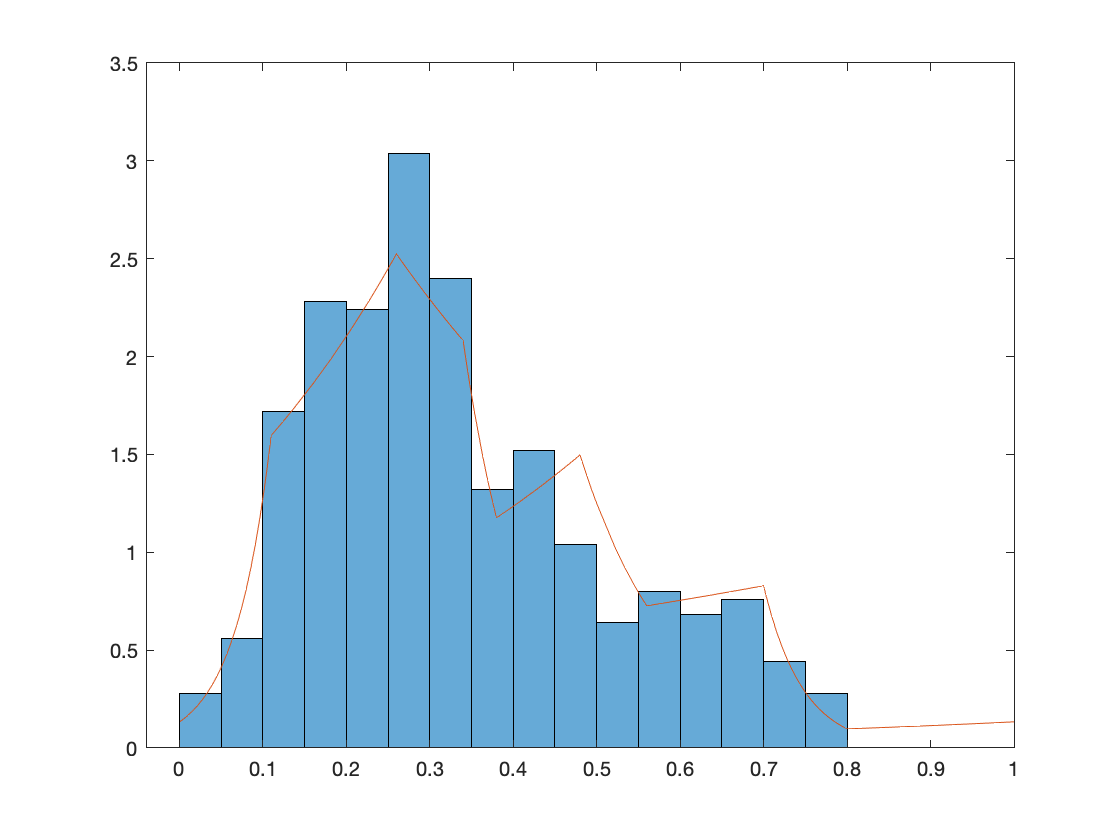

func2(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
                    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
                    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
                    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
                    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
                    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
                    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
                    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))), ...
                    (knots(10) < x)&(x <= knots(11)),exp(chosen_theta(10)*(x-knots(10))/(knots(11)-knots(10)) + chosen_theta(9)*(knots(11)-x)/(knots(11)-knots(10))));
histogram(y, 'Normalization','pdf','BinWidth',0.05)
hold on
fplot(func2, [0,1])
hold off


num_iters = 20000;
burn_in = 1;
proposal_scale = 1e-4

proposal_scale = 1.0000e-04


ll_function = @(x) ll_density(x, knots, y);
constraintFunc = @(x) logspline_constraint(knots, x);
dConstraintFunc = @(x) dlogspline_constraint(knots, x);
[samples, accepts] = runConstrainedMH(num_iters, burn_in, ...
    proposal_scale, initial_guess', ll_function, ...
    constraintFunc, dConstraintFunc)

Finished 1000 iterations.
Current value: -2.051859e+00 -2.839143e-01 6.254651e-01 1.586610e+00 
Finished 2000 iterations.
Current value: -1.871705e+00 -8.847683e-01 2.487481e-01 1.598119e+00 
Finished 3000 iterations.
Current value: -1.577391e+00 -1.133638e+00 6.313087e-03 1.516605e+00 
Finished 4000 iterations.
Current value: -1.651102e+00 4.176407e-03 -9.613152e-01 1.616217e+00 
Finished 5000 iterations.
Current value: -1.787588e+00 2.877436e-01 -1.266109e+00 1.835605e+00 
Finished 6000 iterations.
Current value: -1.564598e+00 3.001073e-01 -1.499053e+00 2.064678e+00 
Finished 7000 iterations.
Current value: -1.109681e+00 4.307127e-01 -1.709335e+00 1.870332e+00 
Finished 8000 iterations.
Current value: -1.602092e+00 1.069643e-02 -2.381753e+00 1.717503e+00 
Finished 9000 iterations.
Current value: -2.148787e+00 1.094129e-01 -2.449238e+00 1.591979e+00 
Finished 10000 iterations.
Current value: -2.405000e+00 -7.748112e-02 -2.298170e+00 1.591904e+00 
Finished 11000 iterations.
Current val

samples =    -2.0219   -2.0173   -2.0205   -2.0321   -2.0127   -2.0198   -2.0358   -2.0199   -2.0240   -2.0271   -2.0341   -2.0273   -2.0337   -2.0296   -2.0356   -2.0226   -2.0311   -2.0395   -2.0405   -2.0539   -2.0513   -2.0326   -2.0346   -2.0435   -2.0484   -2.0415   -2.0212   -2.0037   -2.0034   -2.0007   -2.0050   -1.9888   -1.9907   -1.9930   -2.0003   -1.9992   -2.0226   -2.0224   -2.0250   -2.0296   -2.0262   -2.0413   -2.0391   -2.0496   -2.0570   -2.0681   -2.0631   -2.0647   -2.0386   -2.0315
    0.4684    0.4704    0.4728    0.4645    0.4630    0.4538    0.4431    0.4323    0.4158    0.4147    0.3986    0.4089    0.4226    0.4052    0.3997    0.4009    0.4013    0.3967    0.3921    0.3716    0.3637    0.3592    0.3682    0.3659    0.3774    0.3792    0.3785    0.3780    0.3942    0.3940    0.3920    0.3837    0.3837    0.3854    0.4057    0.3982    0.4042    0.4072    0.4184    0.4105    0.4028    0.3930    0.3836    0.3825    0.3747    0.3735    0.3875    0.3980    0.398

accepts =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


mean(accepts)

ans = 0.9988

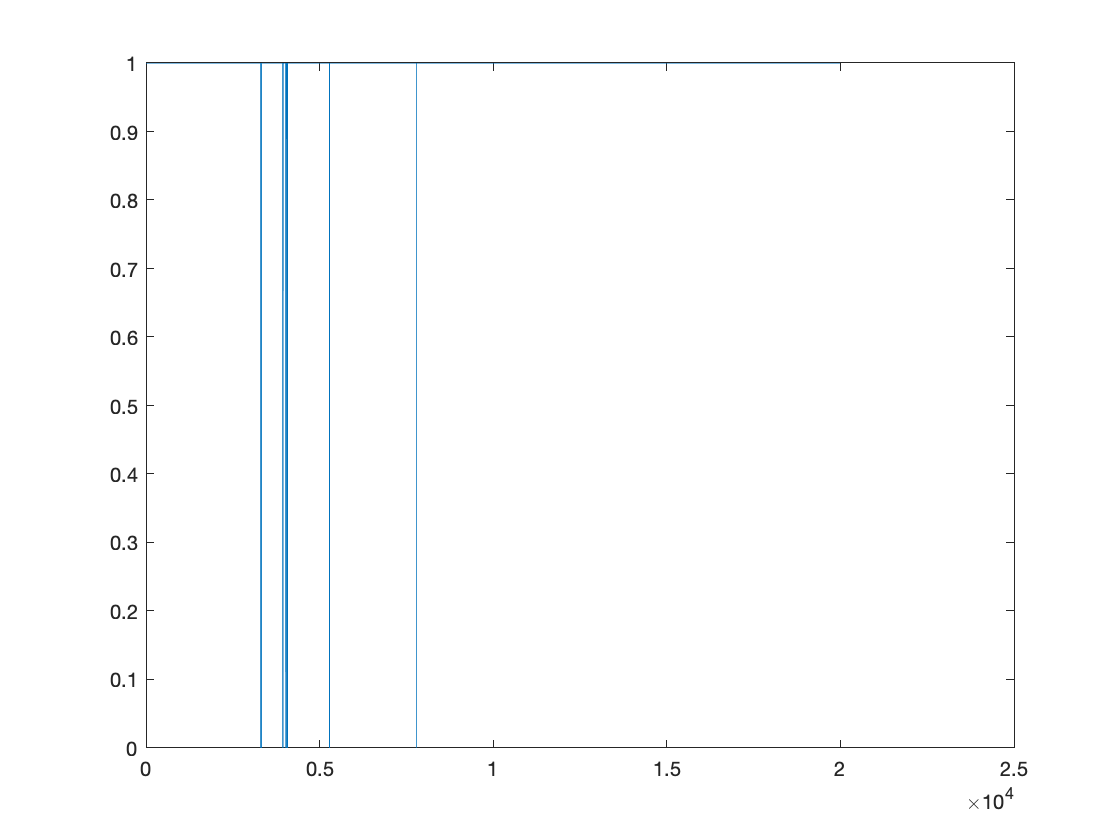

save("MH_logsplineDraws_other.mat",'samples');

plot(accepts)

% I will need to get a point estimator at some point, but for now let's
% just choose a theta and see if I can plot it.
mean_value = mean(samples')';
mean_diff = samples - mean_value;
[~,num_cols] = size(mean_diff);
mag_mean_diff = zeros(1,num_cols);
for i=1:num_cols
    mag_mean_diff(i) = norm(mean_diff(:,i), 2);
end
[~,min_index] = min(mag_mean_diff);

% fplot(y, [0,1])
[~,num_samples] = size(samples);
character_array = ["1"];
prev_sample = samples(:,1);
chosen_theta = initial_guess;
func1(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
                    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
                    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
                    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
                    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
                    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
                    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
                    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))), ...
                    (knots(10) < x)&(x <= knots(11)),exp(chosen_theta(10)*(x-knots(10))/(knots(11)-knots(10)) + chosen_theta(9)*(knots(11)-x)/(knots(11)-knots(10))));
my_plot = fplot(func1, [0,1]);
my_plot

my_plot =   FunctionLine with properties:

     Function: [1×1 symfun]
       XRange: [0 1]
        Color: [0 0.4470 0.7410]
    LineStyle: '-'
    LineWidth: 0.5000

  Show all properties


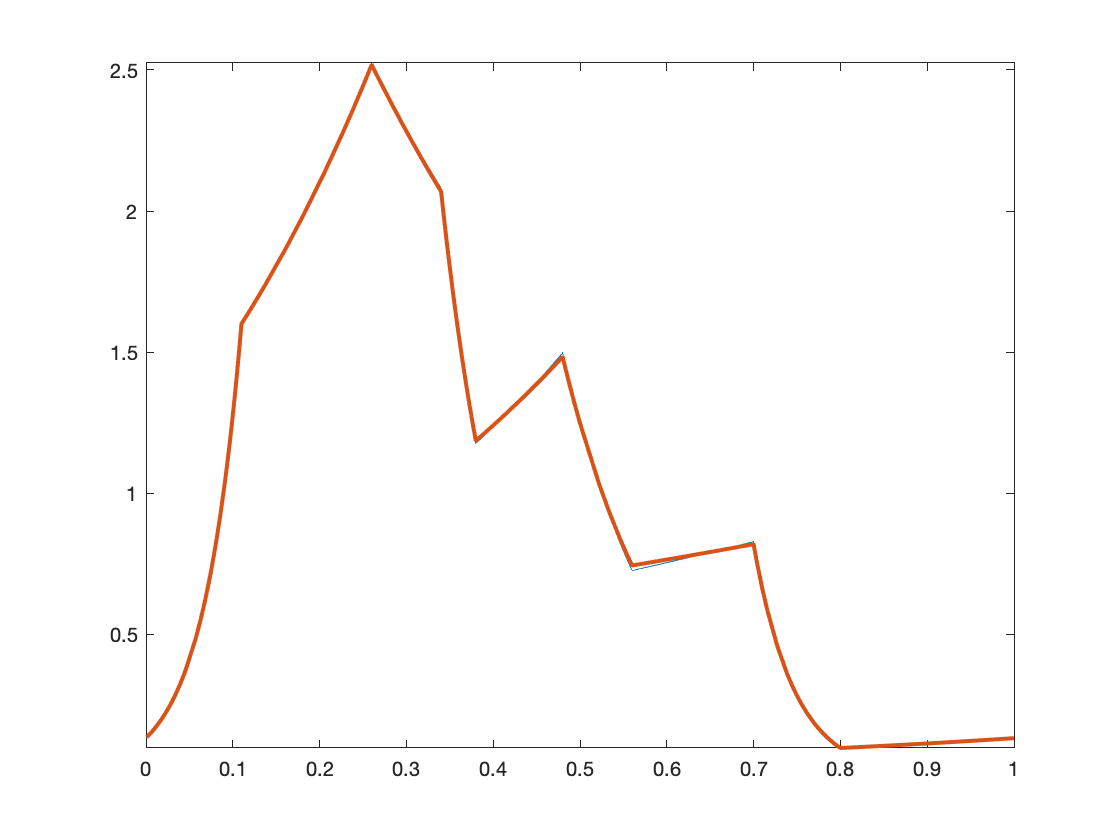

2


my_plot =   FunctionLine with properties:

     Function: [1×1 symfun]
       XRange: [0 1]
        Color: [0.8500 0.3250 0.0980]
    LineStyle: '-'
    LineWidth: 2

  Show all properties


for i = 1:2
    curr_sample = samples(:,i);
    if ~isequal(curr_sample, prev_sample)
        character_array(end+1) = int2str(i);
        disp(int2str(i));
        prev_sample = curr_sample;
        
        syms func2(x)
        chosen_theta = prev_sample;
        func2(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
                    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
                    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
                    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
                    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
                    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
                    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
                    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))), ...
                    (knots(10) < x)&(x <= knots(11)),exp(chosen_theta(10)*(x-knots(10))/(knots(11)-knots(10)) + chosen_theta(9)*(knots(11)-x)/(knots(11)-knots(10))));
        hold on
        my_plot = fplot(func2, [0,1]);
        set(my_plot, 'LineWidth',2);
        my_plot
%         fplot(func2, [0,1])
        hold off
    end
end


% hold on
% histogram(y, 'Normalization','pdf','BinWidth',0.01)
% % legend(character_array)
% hold off

% double(int(func1, 0, 1))
% double(int(f, 0, 1))

mean_value = mean(samples')';
mean_diff = samples - mean_value;
[~,num_cols] = size(mean_diff);
mag_mean_diff = zeros(1,num_cols);
for i=1:num_cols
    mag_mean_diff(i) = norm(mean_diff(:,i), 2);
end
[~,min_index] = min(mag_mean_diff);
chosen_theta = samples(:,min_index);
func1(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
                    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
                    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
                    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
                    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
                    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
                    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
                    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))), ...
                    (knots(10) < x)&(x <= knots(11)),exp(chosen_theta(10)*(x-knots(10))/(knots(11)-knots(10)) + chosen_theta(9)*(knots(11)-x)/(knots(11)-knots(10))));
my_plot = fplot(func1, [0,1]);
set(my_plot, 'LineWidth',2);
my_plot

my_plot =   FunctionLine with properties:

     Function: [1×1 symfun]
       XRange: [0 1]
        Color: [0 0.4470 0.7410]
    LineStyle: '-'
    LineWidth: 2

  Show all properties



[num_rows, ~] = size(samples);
upper95s = zeros(1,num_rows);
lower5s = zeros(1,num_rows);
for i=1:num_rows
    upper95s(i) = quantile(samples(i,:),0.95);
    lower5s(i) = quantile(samples(i,:),0.05);
end

chosen_theta = upper95s;
syms func1(x)
hold on
func1(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
                    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
                    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
                    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
                    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
                    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
                    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
                    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))), ...
                    (knots(10) < x)&(x <= knots(11)),exp(chosen_theta(10)*(x-knots(10))/(knots(11)-knots(10)) + chosen_theta(9)*(knots(11)-x)/(knots(11)-knots(10))));
my_plot = fplot(func1, [0,1]);
set(my_plot, 'LineWidth',2);
my_plot

my_plot =   FunctionLine with properties:

     Function: [1×1 symfun]
       XRange: [0 1]
        Color: [0.8500 0.3250 0.0980]
    LineStyle: '-'
    LineWidth: 2

  Show all properties


hold off


chosen_theta = lower5s;
syms func1(x)
hold on
func1(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
                    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
                    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
                    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
                    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
                    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
                    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
                    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))), ...
                    (knots(10) < x)&(x <= knots(11)),exp(chosen_theta(10)*(x-knots(10))/(knots(11)-knots(10)) + chosen_theta(9)*(knots(11)-x)/(knots(11)-knots(10))));
my_plot = fplot(func1, [0,1]);
set(my_plot, 'LineWidth',2);
my_plot

my_plot =   FunctionLine with properties:

     Function: [1×1 symfun]
       XRange: [0 1]
        Color: [0.9290 0.6940 0.1250]
    LineStyle: '-'
    LineWidth: 2

  Show all properties


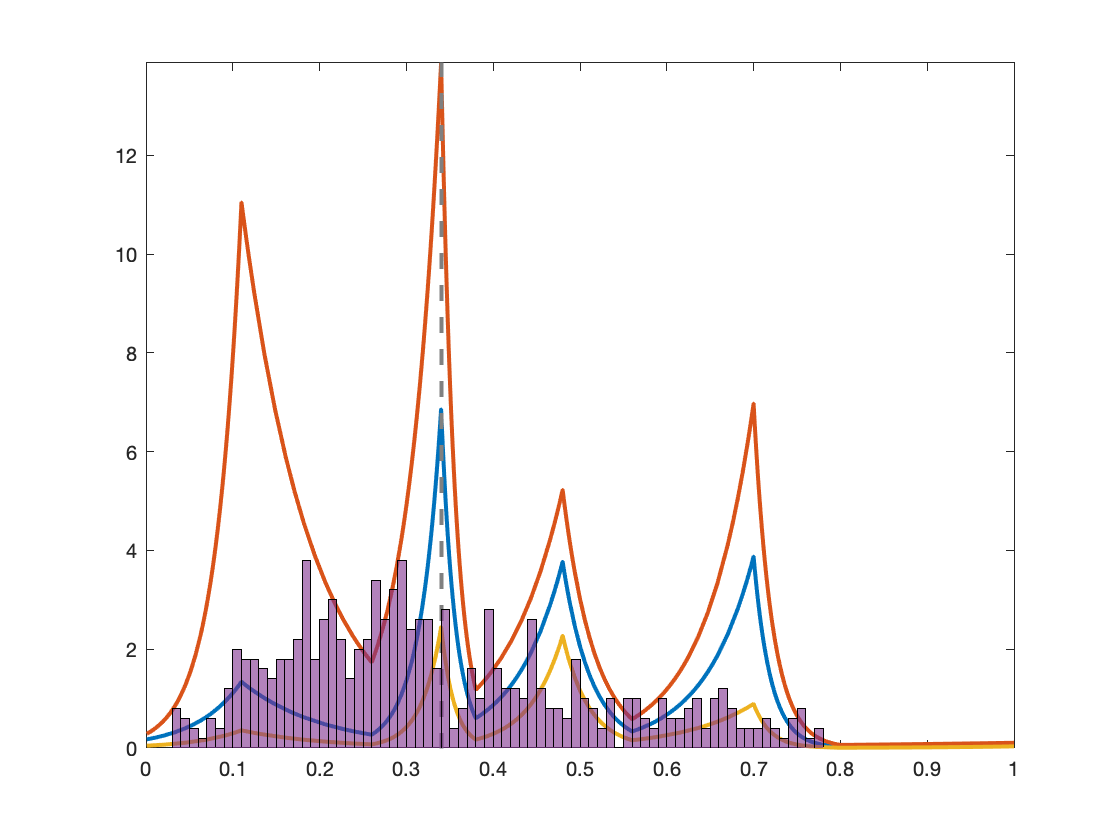

hold off

hold on
histogram(y, 'Normalization','pdf','BinWidth',0.01)
% legend(character_array)
hold off